### Simulink and simscape step response

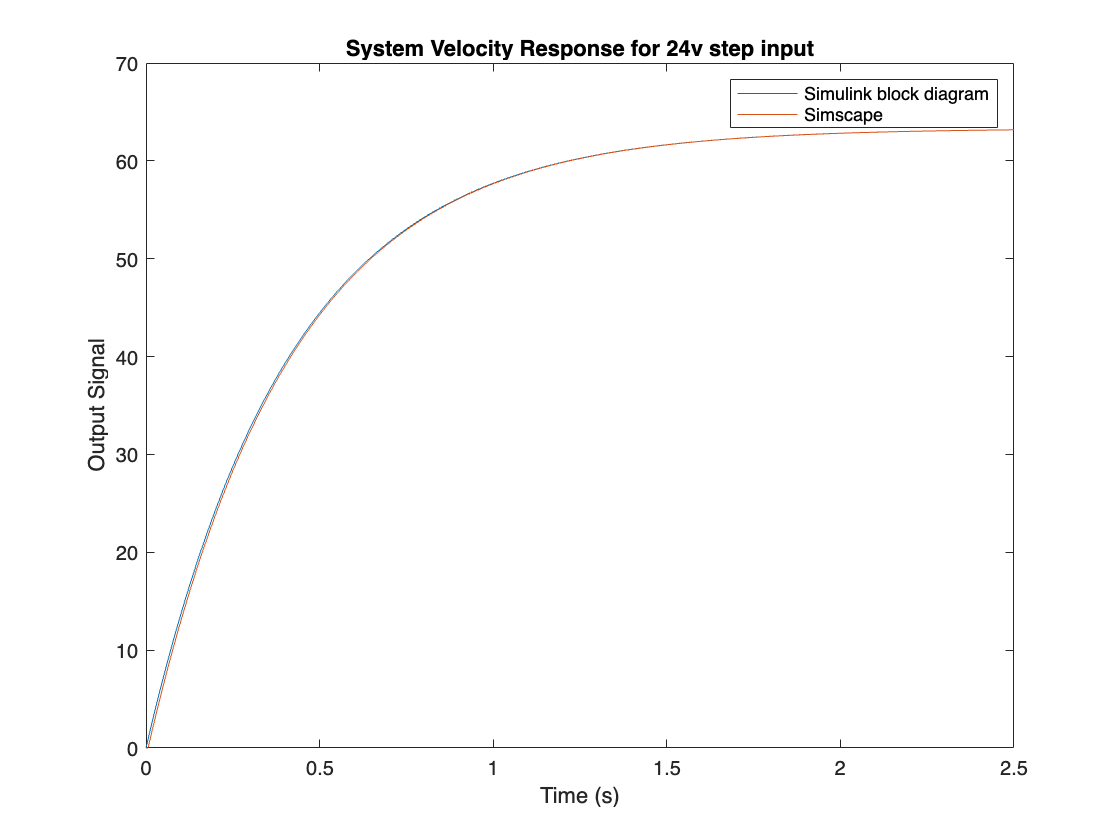

model_name = 'excercise2_2'; 
load_system(model_name);

runningtime = num2str(2.5);

set_param(model_name, 'StopTime', runningtime); 

simOut = sim(model_name);


sim_time12 = simOut.tout;
output_signal12 = simOut.logsout.getElement('thetadot_ Simscape2').Values.Data; 


model_name = 'excercise2_2'; 
load_system(model_name);


set_param(model_name, 'StopTime', runningtime); 
set_param(model_name, 'Solver', 'ode45');
set_param(model_name, 'MaxStep', '0.001');

simOut = sim(model_name);


sim_time22 = simOut.tout;
output_signal22 = simOut.logsout.getElement("velocity2").Values.Data; 

figure;
plot(sim_time22, output_signal22);
title('System Velocity Response for 24v step input');
xlabel('Time (s)');
ylabel('Output Signal');
hold on

runningtimeint = str2num(runningtime);
tvec = linspace(0,runningtimeint,length(output_signal12));

plot(tvec, output_signal12)
legend("Simulink block diagram", "Simscape")
hold off